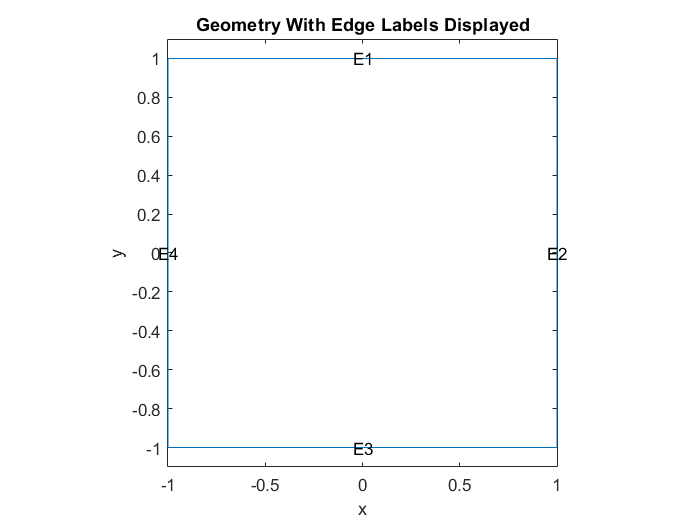

%Annel Pacheco A01551933

numberOfPDE=1;
model= createpde(numberOfPDE);
geometryFromEdges(model,@squareg);
pdegplot(model,'EdgeLabels','on');
ylim([-1.1 1.1]);
axis equal
title 'Geometry With Edge Labels Displayed'
xlabel x
ylabel y

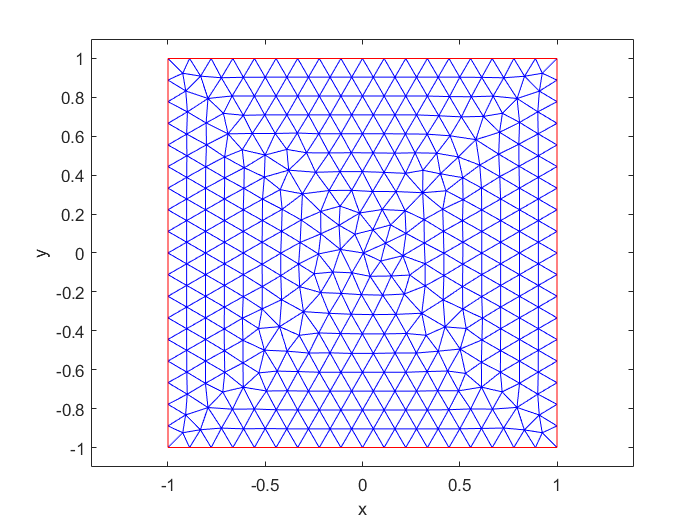


m=1;
d=0;
c=1;
a=0;
f=0;

specifyCoefficients(model,'m',m,'d',d,'c',c,'a',a,'f',f);
applyBoundaryCondition(model,'dirichlet','Edge',[4,2],'u',0);
applyBoundaryCondition(model,'neumann','Edge',[1,3],'g',0);

generateMesh(model);
figure
pdemesh(model);
ylim([-1.1 1.1]);
axis equal
xlabel x
ylabel y


u0= @(location)    atan(cos((pi*location.x)/2));
ut0= @(location)   3.*sin(pi*location.x).*exp(sin((pi.*location.y)/2));

setInitialConditions(model,u0,ut0);

%Now we solve the equation, Use the following code without changes
n=31;
tlist= linspace(0,5,n);
model.SolverOptions.ReportStatistics='on';
result= solvepde(model,tlist);

457 successful steps
38 failed attempts
992 function evaluations
1 partial derivatives
113 LU decompositions
991 solutions of linear systems


u = result.NodalSolution

u =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   

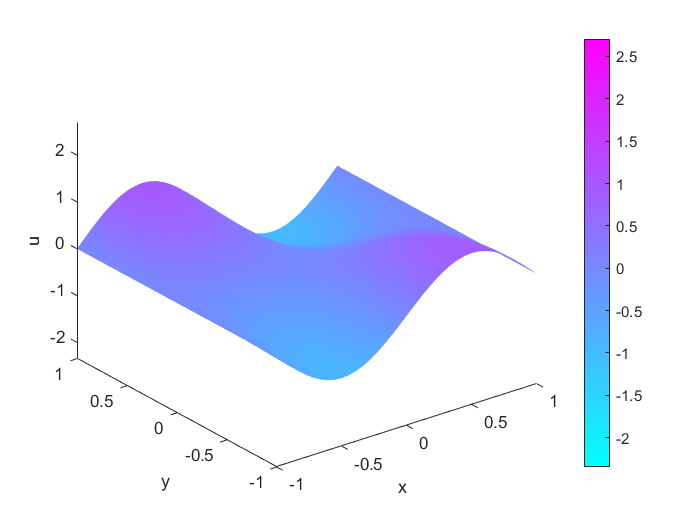

% 
figure
umax= max(max(u));
umin= min(min(u));
for i= 1:n
    pdeplot(model,'XYData',u(:,i),'ZData',u(:,i),'ZStyle','continuous','Mesh','off');
    axis([-1 1 -1 1 umin umax]);
    caxis([umin umax]);
    xlabel x
    ylabel y
    zlabel u
    M(i) = getframe;
end